% 两连杆机器人的动力学例子，采用Lagrange-Eular方程
% 1. 手动推导概念
% 2. 采用DH法则构建的函数推导，满足所有的串联型机器人的动力学推导

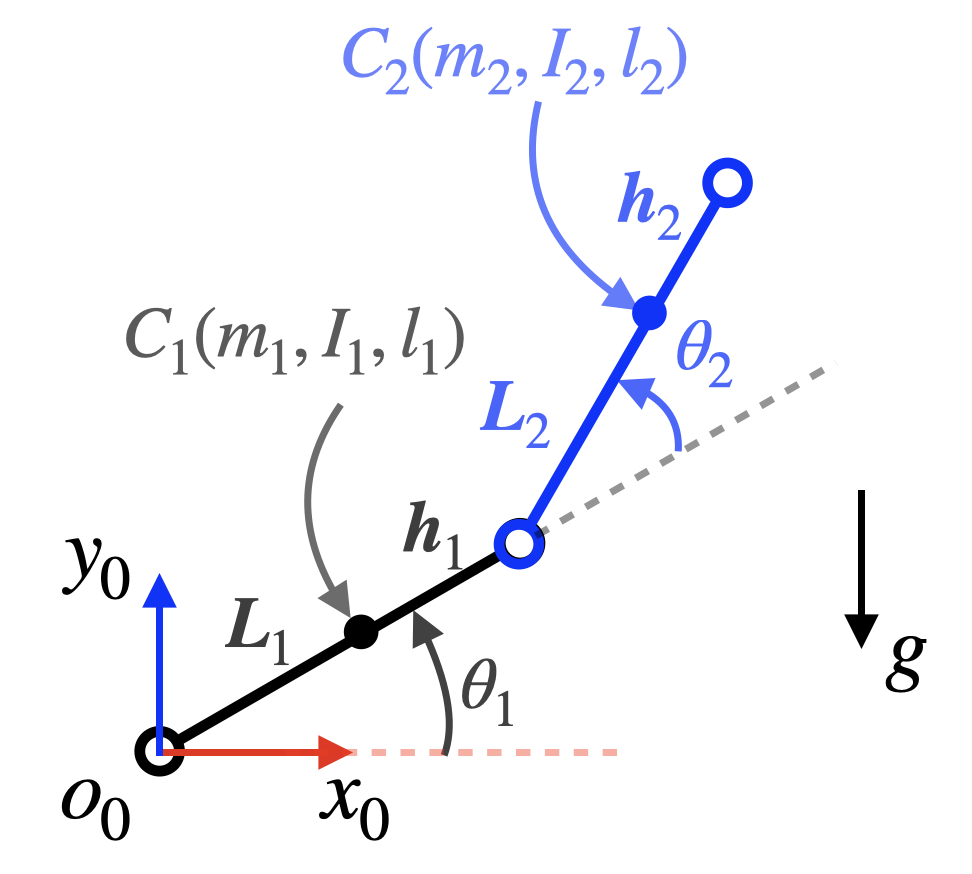，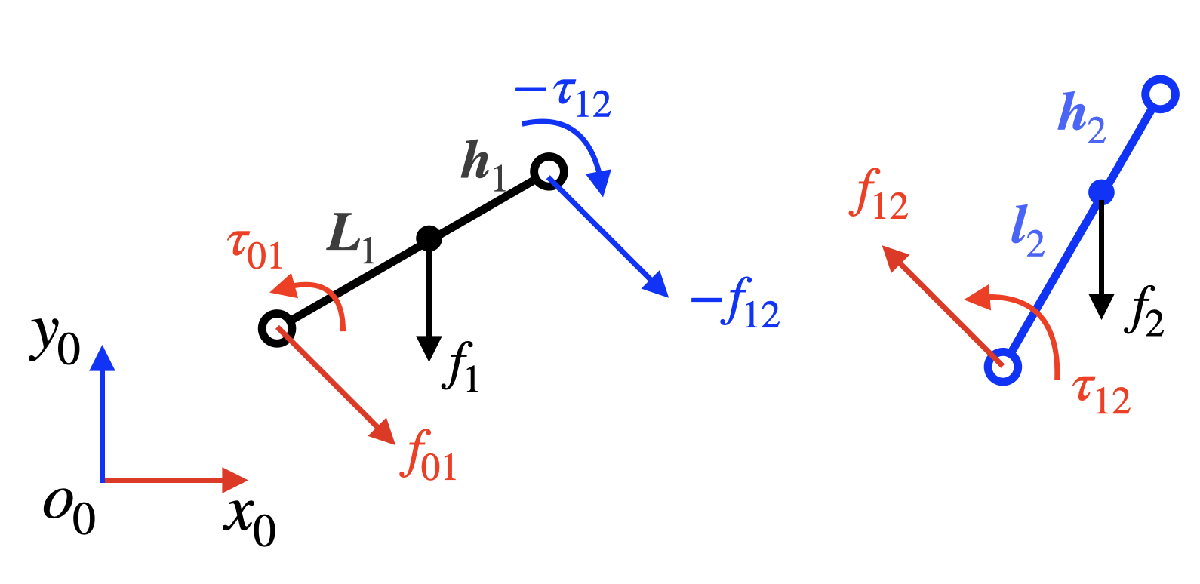

% 手动推导
clc
clear
close all

% 质量集中，无惯性矩阵，连杆长度与质心位置重合
syms m1 Ic1 d1 L1 
syms m2 Ic2 d2 L2 
syms g 
syms theta1 omega1 epsilon1
syms omega2 epsilon2


% 质量矩阵
M1 = diag([m1,m1,0]);
M2 = diag([m2,m2,0]);

% 位置
q = [theta1; d2];
Xc1 = rotz(theta1) * [d1; 0; 0];
Xc2 = rotz(theta1) * [d2; 0; 0];


% 速度
omega = [omega1; omega2];
Vc1 = jacobian(Xc1,q)*omega;
Vc2 = jacobian(Xc2,q)*omega;

% 动能
K1 = (1/2)*Vc1.'*M1*Vc1 + (1/2)*Ic1*omega1^2;
K2 = (1/2)*Vc2.'*M2*Vc2 + (1/2)*Ic2*(omega1 + omega2)^2;
K = K1 + K2;

% 势能
P1 = m1*g*d1*sin(theta1);
P2 = m2*g*d2*sin(theta1);
P = P1 + P2;

% 拉格朗日方程
L = K - P;

% 利用运动方程计算力矩方程
epsilon = [epsilon1;  epsilon2];

dLddq = [jacobian(L,omega1);   jacobian(L,omega2)];   %
ddLdqddt = jacobian(dLddq,q)*omega + jacobian(dLddq,omega)* epsilon;    %
dLdq =  [jacobian(L,theta1);     jacobian(L,d2)];     %

% 输出结果
tau = simplify(ddLdqddt - dLdq);
H = simplify(jacobian(tau, epsilon))

$$H = \left(\begin{array}{cc} m_{1}\,{d_{1}}^{2}+m_{2}\,{d_{2}}^{2}+{\mathrm{Ic}}_{1}+{\mathrm{Ic}}_{2} & {\mathrm{Ic}}_{2}\\ {\mathrm{Ic}}_{2} & {\mathrm{Ic}}_{2}+m_{2} \end{array}\right)$$

C = simplify(jacobian(tau, omega))

$$C = \left(\begin{array}{cc} 2\,d_{2}\,m_{2}\,\omega_{2} & 2\,d_{2}\,m_{2}\,\omega_{1}\\ -2\,d_{2}\,m_{2}\,\omega_{1} & 0 \end{array}\right)$$

G = simplify(jacobian(tau, g)*g)

$$G = \left(\begin{array}{c} g\,\cos\left(\theta_{1}\right)\,\left(d_{1}\,m_{1}+d_{2}\,m_{2}\right)\\ g\,m_{2}\,\sin\left(\theta_{1}\right) \end{array}\right)$$

clc
clear
close all

syms q1 q2 m1 m2 d1 d2 Lc1 Lc2 Ix1 Iy1 Iz1 Ix2 Iy2 Iz2 dq1 dq2 ddq1 ddq2 

% DH parameters
%             alpha a   d   theta
dh_params = [ 0,   d1,  0,  q1; 
              0,   d2,  0,  0];

       
%               x   y   z
mass_center = [d1, 0,  0;  
               d2, 0,  0;  ];

%
mass = [m1,m2];

% 只有主惯性 
inertia_1 = [Ix1, 0,    0;
             0,   Iy1,  0;
             0,   0,    Iz1];
         
inertia_2 = [Ix2,   0,      0;
             0,     Iy2,    0; 
             0,     0,      Iz2];

% 构成惯性张量
inertia_tensor(:,:,1) = inertia_1;
inertia_tensor(:,:,2) = inertia_2;

[h,c, g] = LagrangianDynamics1(dh_params, mass, mass_center,inertia_tensor)

$$h = \left(\begin{array}{cc} {\mathrm{Iz}}_{1}+{\mathrm{Iz}}_{2}+3\,{d_{1}}^{2}\,m_{1}+3\,{d_{1}}^{2}\,m_{2}+{d_{2}}^{2}\,m_{2}+4\,d_{1}\,d_{2}\,m_{2} & 0\\ 0 & 0 \end{array}\right)$$

$$c = \left(\begin{array}{cc} 0 & 0\\ 0 & 0 \end{array}\right)$$

$$g = \left(\begin{array}{c} \mathrm{gc}\,\cos\left(\bar{q_{1}}\right)\,\left(\bar{d_{1}}\,\bar{m_{1}}+\bar{d_{1}}\,\bar{m_{2}}+\bar{d_{2}}\,\bar{m_{2}}+\frac{{\left|d_{1}\right|}^{2}\,\bar{m_{1}}}{\bar{d_{1}}}+\frac{{\left|d_{2}\right|}^{2}\,\bar{m_{2}}}{\bar{d_{2}}}\right)\\ 0 \end{array}\right)$$

function [H,C,G] = LagrangianDynamics1(dh_list, mass_list, mass_center_list, inertia_tensor_list)

[rows, columns] = size(dh_list);
number_of_links = rows;
if columns ~= 4
    error('wrong DH parameters!')
end

for i = 1:number_of_links
    % 根据关节数量定义关节位置，速度，加速度符号
    eval(['syms ','q',num2str(i),';']);
    eval(['syms ','dq',num2str(i),';']);
    eval(['syms ','ddq',num2str(i),';']);
    eval(['q(i)=','q',num2str(i),';']);
    eval(['dq(i)=','dq',num2str(i),';']);
    eval(['ddq(i)=','ddq',num2str(i),';']);
end

% 计算每个连杆坐标系在前一个坐标系下的表达
T = sym([]);

% 存储杆件的齐次坐标变化矩阵
for i = 1:number_of_links
    dh = dh_list(i,:);
    alpha(i) = dh(1);
    a(i) = dh(2);
    d(i) = dh(3);
    q(i) = dh(4);

    % 标注DH方法的齐次坐标变换矩阵
    T(:,:,i) = [cos(q(i)), -sin(q(i))*cos(alpha(i)),    sin(alpha(i))*sin(q(i)),    a(i)*cos(q(i));
                sin(q(i)), cos(q(i))*cos(alpha(i)),     -sin(alpha(i))*cos(q(i)),   a(i)*sin(q(i));
                0,         sin(alpha(i)),               cos(alpha(i)),              d(i);
                0,         0,                           0,                          1];
end

% 计算每个连杆坐标系在{0}系下的表达
T0 = sym([]);
for i = 1:number_of_links
    T0(:,:,i) = eye(4,4);
    for j = 1:i
        T0(:,:,i) = T0(:,:,i)*T(:,:,j);
    end
    T0(:,:,i) = simplify(T0(:,:,i));
end

% 计算每个连杆的伪惯性矩阵
J = sym([]);
for i = 1:number_of_links
    mass = mass_list(i);
    mass_center = mass_center_list(1,:);
    inertia = inertia_tensor_list(:,:,i);

    JMatrixB(1,1) = (-inertia(1,1) + inertia(2,2) + inertia(3,3))/2;
    JMatrixB(1,2) = inertia(1,2);
    JMatrixB(1,3) = inertia(1,3);
    JMatrixB(1,4) = mass * mass_center(1);
    
    JMatrixB(2,1) = inertia(2,1);
    JMatrixB(2,2) = ( inertia(1,1) - inertia(2,2) + inertia(3,3))/2;
    JMatrixB(2,3) = inertia(2,3);
    JMatrixB(3,4) = mass * mass_center(2);
    
    JMatrixB(3,1) = inertia(3,1);
    JMatrixB(3,2) = inertia(3,2);
    JMatrixB(3,3) = ( inertia(1,1) + inertia(2,2) - inertia(3,3))/2;
    JMatrixB(3,4) = mass * mass_center(3);
    
    JMatrixB(4,1) = JMatrixB(1,4);
    JMatrixB(4,2) = JMatrixB(2,4);
    JMatrixB(4,3) = JMatrixB(3,4);
    JMatrixB(4,4) = mass;

    J(:,:,i) = JMatrixB;
end


% 计算H(q),由H(q)对称性，只需计算上三角部分
syms tr
for i = 1:number_of_links
    for j = i:number_of_links
        tr = 0;
        for k = j:number_of_links
            tr = tr + trace(eval(['diff(T0(:,:,k),q',num2str(i),')']) ...
                      *J(:,:,k) ...
                      *eval(['diff(transpose(T0(:,:,k)),q',num2str(j),')']));
        end
        H(i,j) = simplify(tr);
        H(j,i) = H(i,j);
    end
end

% 计算C(q)
for i = 1:number_of_links
    for j = 1:number_of_links
        c = 0;
        for k = 1:number_of_links
            c = c + 1/2*(eval(['diff(H(i,j),q',num2str(k),')'])...
                        + eval(['diff(H(i,k),q',num2str(j),')'])...
                        - eval(['diff(H(j,k),q',num2str(i),')']))*eval(['dq',num2str(k)]);
        end
        C(i,j) = simplify(c);
    end
end

syms gc
g = [0;-gc;0;1];

% 计算G(q)
for i = 1:number_of_links
    gi = 0;
    for j = 1:number_of_links
        gi = gi - mass_list(j)*g'*eval(['diff(T0(:,:,j),q',num2str(i),')']) * [mass_center_list(j,:),1]';
    end
    G(i) = simplify(gi);
end
G = G';

end
